%Setting Up

clear all
close all
clc
currentFolder = '/Users/alysolberg/Dropbox (HMS)/hyperData'

currentFolder = '/Users/alysolberg/Dropbox (HMS)/hyperData'

saveFolder= '/Users/alysolberg/Dropbox (HMS)/hyperData/final figures'

saveFolder = '/Users/alysolberg/Dropbox (HMS)/hyperData/final figures'

cd(currentFolder)
load masterStackTable.mat
load CompiledPhysio_final.mat

%Creating Color Map

colormap=[0.447 0.737 0.831 ; 1 0.647 0];

%Setting up to make Histogram

UniqueIds=cell2table(unique(alldataV.Master_ID));
masterIDs=cell2table(masterID.Master_ID);
AgeIndex=ismember(masterIDs,UniqueIds);
Age=array2table(masterID.AgeAtExp_InjectionStart_days_(AgeIndex));
Age.Properties.VariableNames= {'Age'};
AgeID=cell2table(masterIDs.Var1(AgeIndex));
AgeID.Properties.VariableNames={'Master_ID'};
NewAgeIDs=[AgeID, Age];
alldataNew=join(alldataV,NewAgeIDs);

%Graphing the Histogram

y(1,1)=gramm('y',alldataNew.Age,'x',strcmp(alldataNew.Condition_H_C_,'H'),'color',alldataNew.Condition_H_C_)

y =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


y(1,1).set_layout_options('Position',[0 0.8 0.8 0.2],... %Set the position in the figure (as in standard 'Position' axe property)
   'legend',false,... % No need to display legend for side histograms
    'margin_height',[0.02 0.05],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.1 0.02],...
    'redraw',false); %We deactivate automatic redrawing/resizing so that the axes stay aligned according to the margin options
y(1,1).set_names('x','Condition','y','');
y(1,1).stat_boxplot('width',0.5,"dodge",0.4); 
y(1,1).axe_property('YTickLabel','','XTickLabel','','LineWidth',1); 
y(1,1).coord_flip();

y(2,1)=gramm('x',alldataNew.Age,'y','','color',alldataNew.Condition_H_C_)

y =   2×1 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


y(2,1).stat_bin('normalization','probability','geom','stairs',"fill","transparent");
y(2,1).set_names('x','Age','y','Normalized Count','color','Condition')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


y(2,1).set_point_options('base_size',6)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


y(2,1).set_layout_options('Position',[0 0 0.8 0.8],...
    'legend_pos',[0.83 0.39 0.2 0.2],... %We detach the legend from the plot and move it to the top right
    'margin_height',[0.1 0.02],...
    'margin_width',[0.1 0.02],...
    'redraw',false);
y(2,1).axe_property('Ygrid','on','LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



y.set_title('Age Distribution per Condition')

ans =   2×1 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


y.set_color_options('map',colormap)

ans =   2×1 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


y.set_text_options('base_size',10,"big_title_scaling",2,'label_scaling',2,'legend_scaling',1.5,'legend_title_scaling',2)

ans =   2×1 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


figure('Position',[0 0 800 800])
y.draw

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


ans =   2×1 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


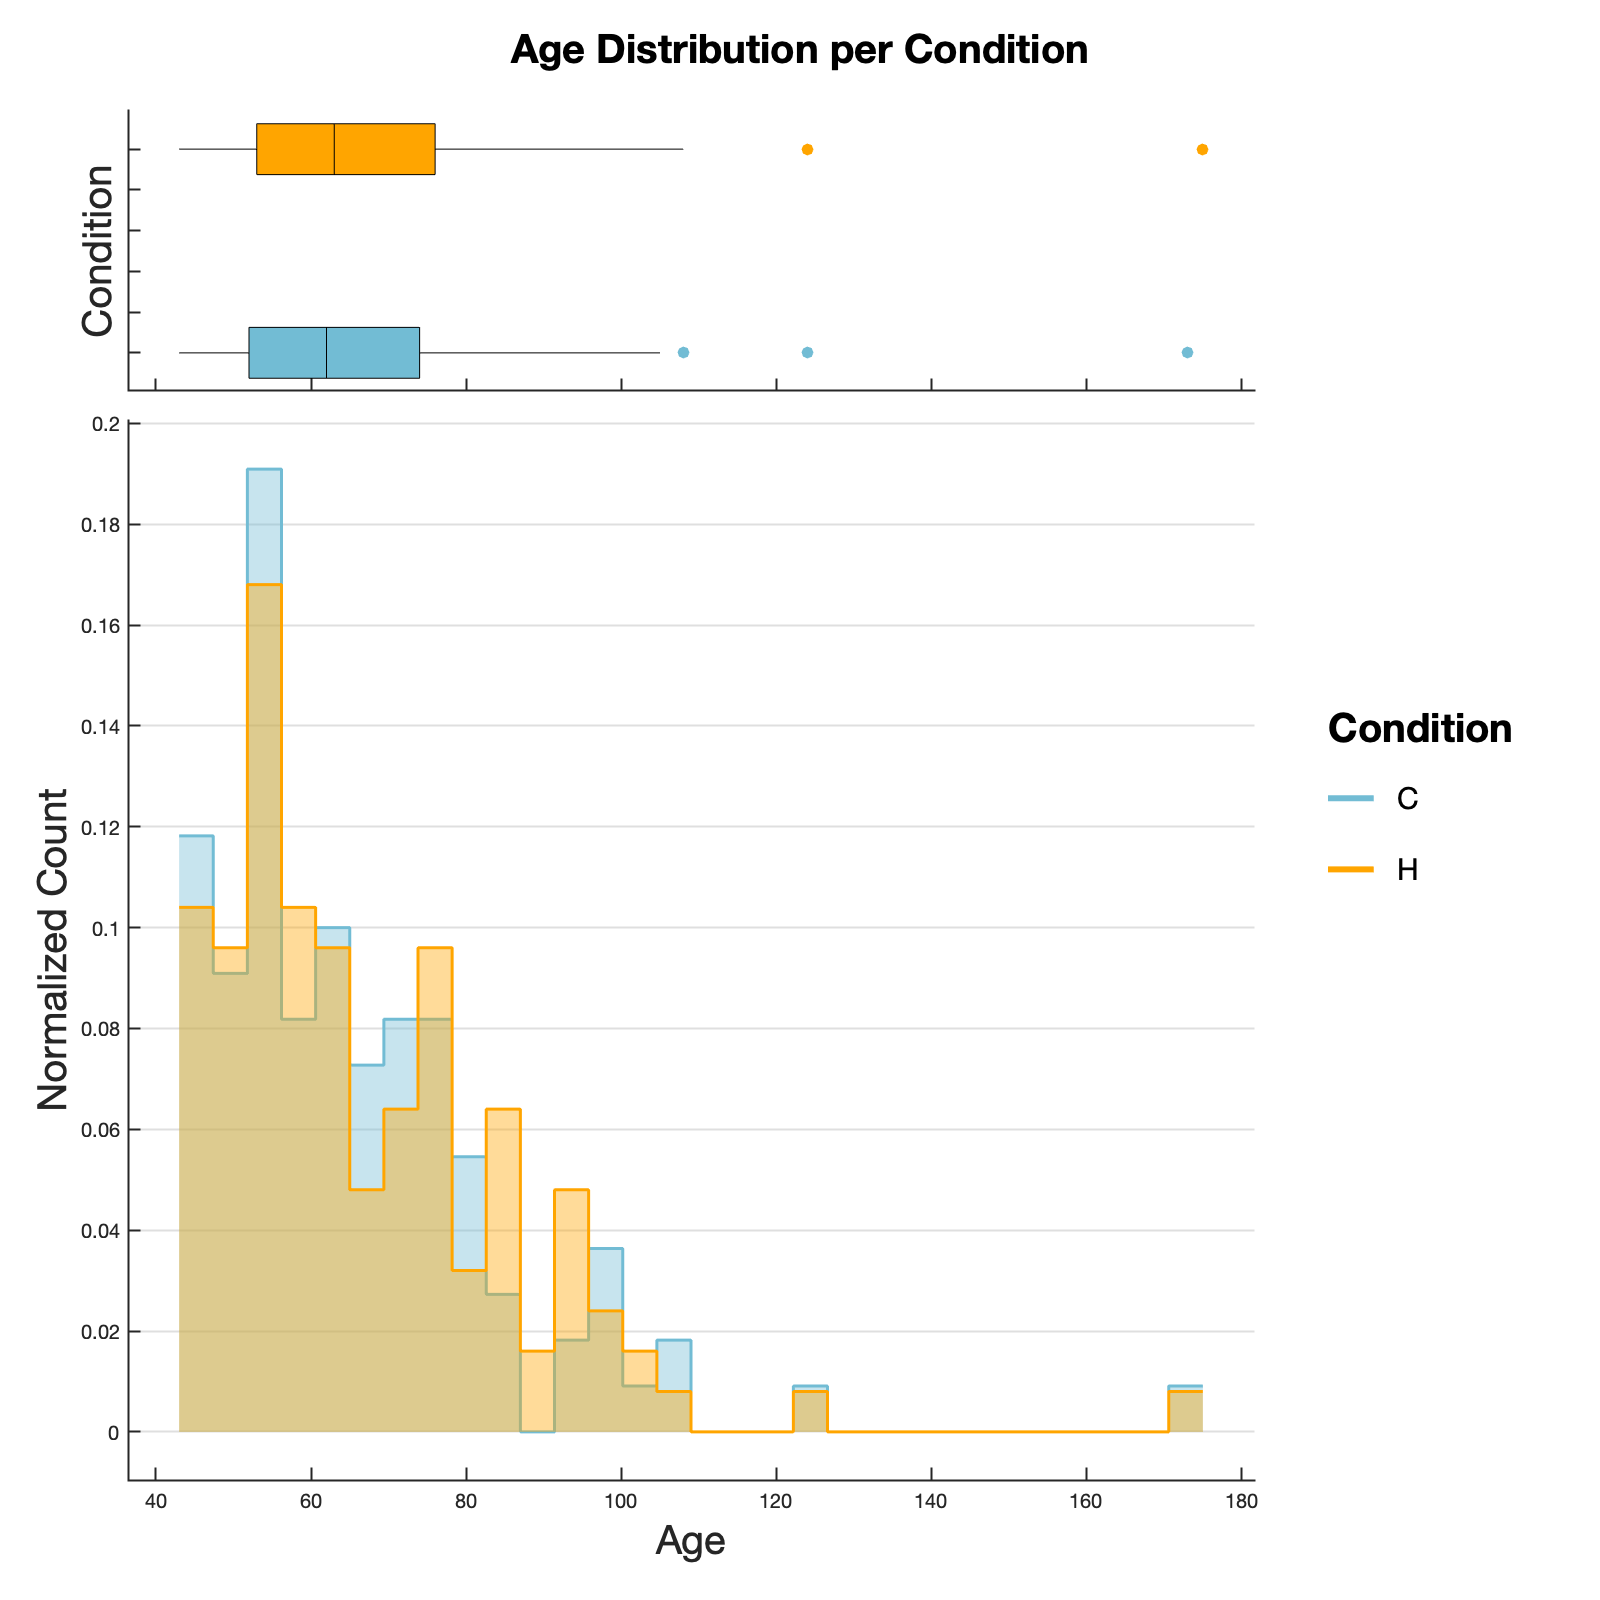


saveas(gcf,'age_distribution','epsc')
saveas(gcf,'age_distribution','jpeg')
saveas(gcf,'age_distribution','fig')

%1x3 same day

p(1,1)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

p =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


p(1,1).geom_point()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


p(1,1).set_names('x','Age','y','Food Intake')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


p(1,1).no_legend;
p(1,1).axe_property('LineWidth',1);


p(1,2)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

p =   1×2 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


p(1,2).geom_point();
p(1,2).set_names('x','Age','y','Temperature')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


p(1,2).no_legend;
p(1,2).axe_property('LineWidth',1);


p(1,3)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

p =   1×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


p(1,3).geom_point();
p(1,3).set_names('x','Age','y','Weight','color','Condition')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


p(1,3).set_layout_options('legend_position',[0.87 0.6 0.2 0.5]);
p(1,3).axe_property('LineWidth',1);

p.set_color_options('map',colormap)

ans =   1×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


p.set_title('Physiology Changes Across Ages: Day 3');
figure('Position',[500 500 1500 550]);
p.set_text_options('base_size',10,"big_title_scaling",2.5,'label_scaling',2.5,"legend_scaling",1.5,"legend_title_scaling",1.75)

ans =   1×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


p.draw

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


ans =   1×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


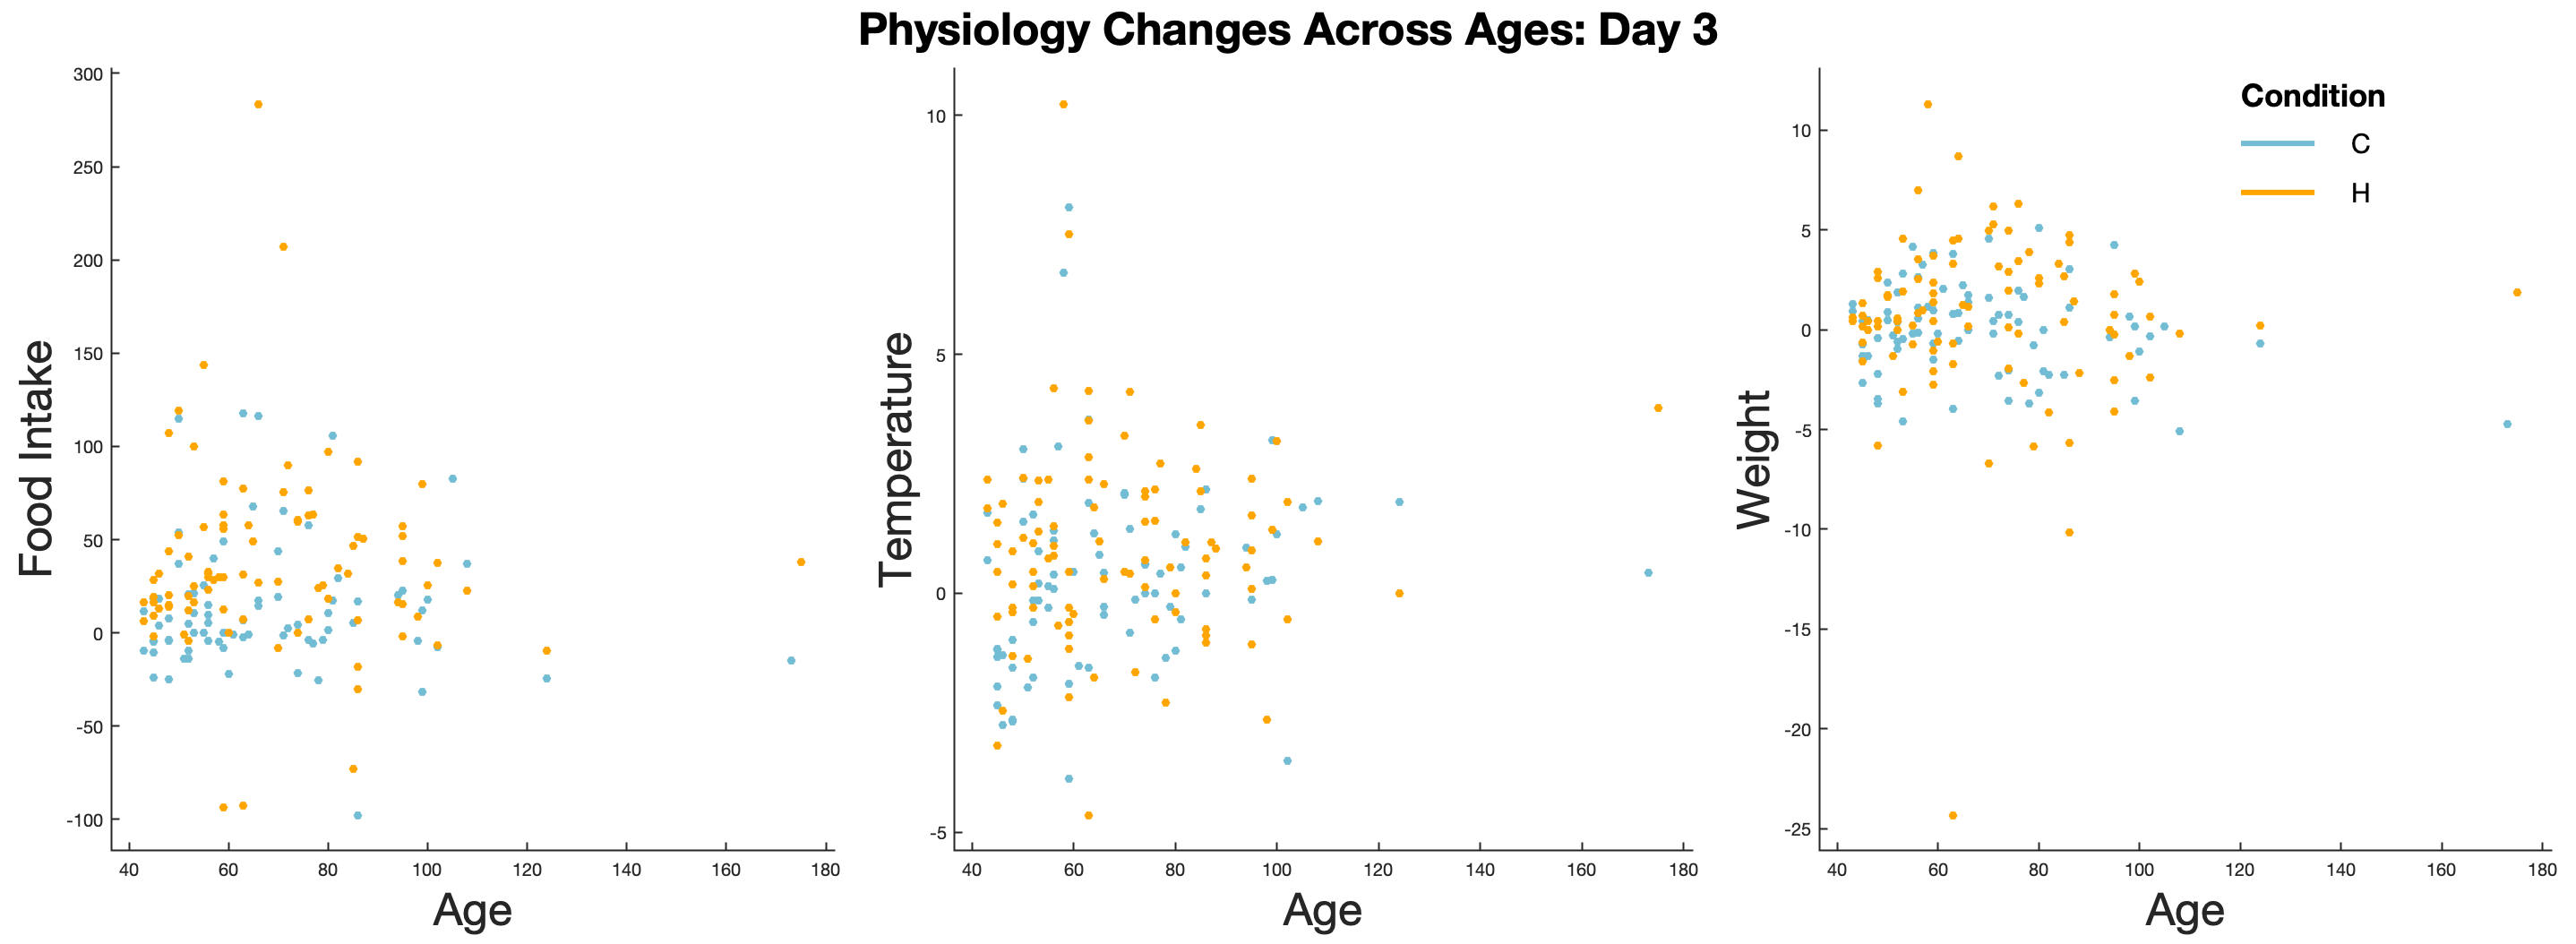



saveas(gcf,'phys_day_three','epsc')
saveas(gcf,'phys_day_three','jpeg')
saveas(gcf,'phys_day_three','fig')

Baseline Weight

o=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.baselineWeight,'color',alldataV.Condition_H_C_)

o =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


o.geom_point();
o.set_names('x','Age','y','Baseline Weight','color','Condition');
o.set_color_options('map',colormap)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


o.set_title('Baseline Weight Across Ages');
o.axe_property('LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


figure('Position',[100 100 650 600]);
o.set_text_options('base_size',10,'big_title_scaling',3,'label_scaling',2.5,"legend_scaling",1.5,"legend_title_scaling",1.5)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


o.draw

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


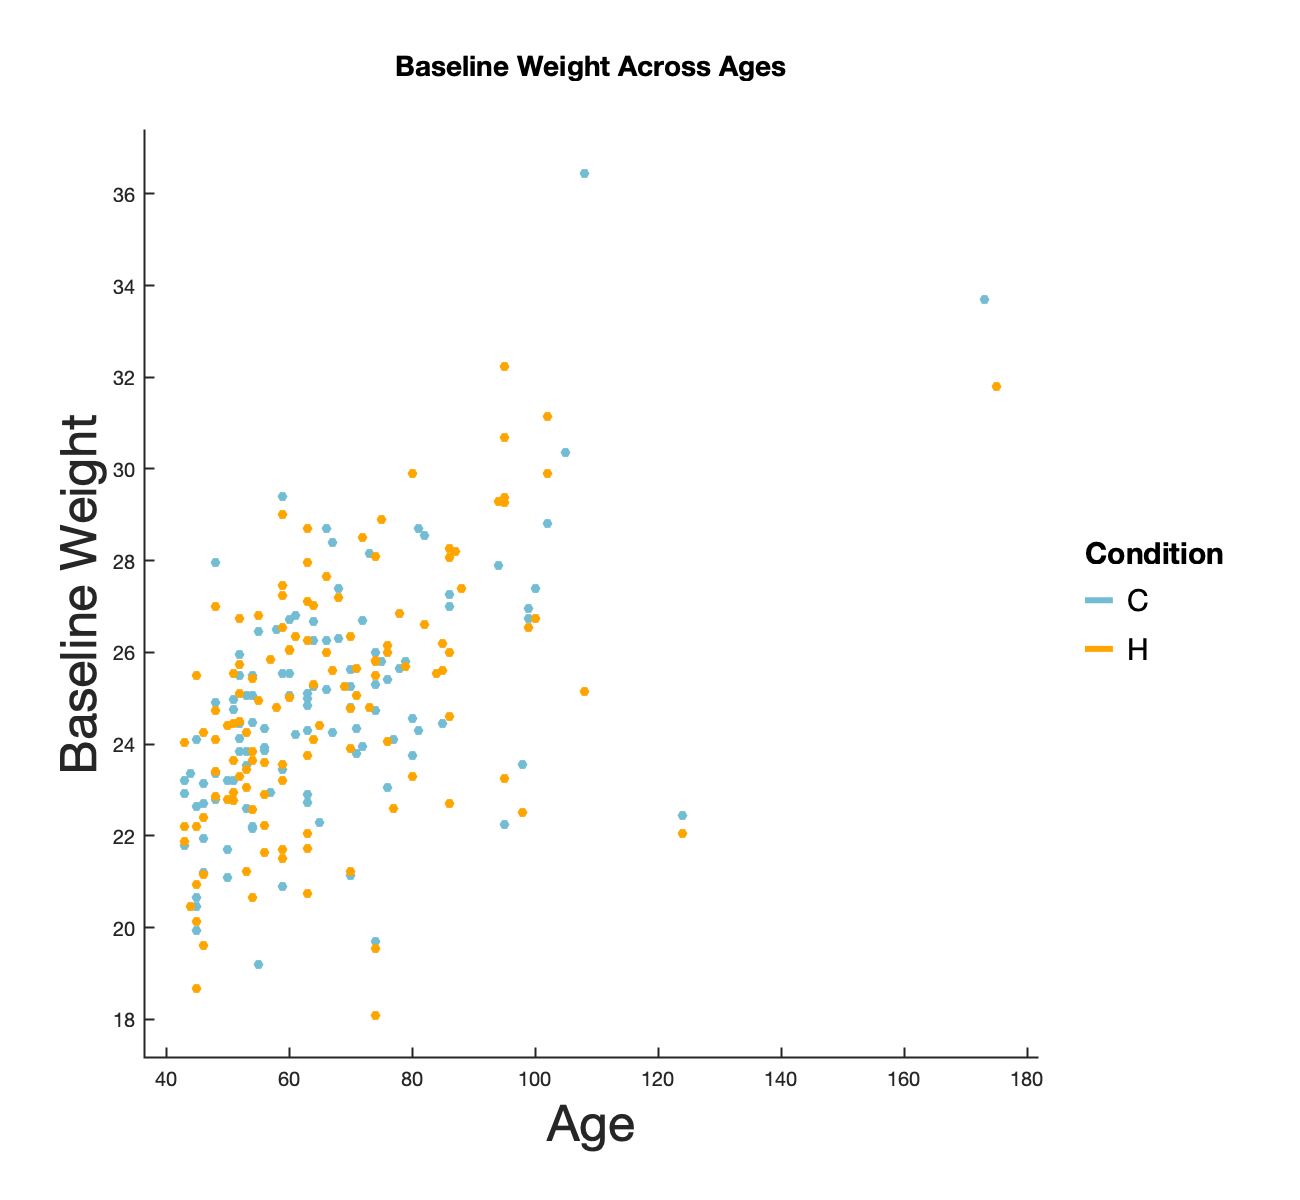


saveas(gcf,'baseline_weight','epsc')
saveas(gcf,'baseline_weight','jpeg')
saveas(gcf,'baseline_weight','fig')

3x3 row: measurement, column, day

%Food
c(1,1)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==1)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(1,1).geom_point()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,1).set_names('x','','y','Food Intake')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,1).no_legend;
c(1,1).axe_property('YLim',[-120 300],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,1).set_title('Day 1');

c(1,2)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==2)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(1,2).geom_point();
c(1,2).set_names('x','','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,2).no_legend;
c(1,2).axe_property('YLim',[-120 300],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,2).set_title('Day 2');

c(1,3)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(1,3).geom_point();
c(1,3).set_names('x','','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,3).no_legend;
c(1,3).axe_property('YLim',[-120 300],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,3).set_title('Day 3');

%Temp
c(2,1)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==1)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(2,1).geom_point()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(2,1).set_names('x','','y','Temperature')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(2,1).no_legend;
c(2,1).axe_property('YLim',[-5 10],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(2,2)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==2)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(2,2).geom_point();
c(2,2).set_names('x','','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(2,2).no_legend;
c(2,2).axe_property('YLim',[-5 10],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(2,3)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(2,3).geom_point();
c(2,3).set_names('x','','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(2,3).no_legend;
c(2,3).axe_property('YLim',[-5 10],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



%Weight
c(3,1)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==1)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(3,1).geom_point()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,1).set_names('x','  ','y','Weight')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,1).no_legend;
c(3,1).axe_property('YLim',[-35 15],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(3,2)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==2)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(3,2).geom_point();
c(3,2).set_names('x','Age','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,2).no_legend;
c(3,2).axe_property('YLim',[-35 15],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(3,3)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(3,3).geom_point();
c(3,3).set_names('x','   ','y','','color','Condition')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,3).no_legend;
c(3,3).set_layout_options('legend_position',[0.9 0.65 0.2 0.5])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,3).axe_property('YLim',[-35 15],'XLim',[30 180],'LineWidth',1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]




c.set_color_options('map',colormap)

ans =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


figure('Position',[0 0 900 900]);
c.set_text_options('base_size',10,"big_title_scaling",2.5,'label_scaling',2.5,"legend_scaling",1,"legend_title_scaling",1)

ans =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c.draw

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


ans =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


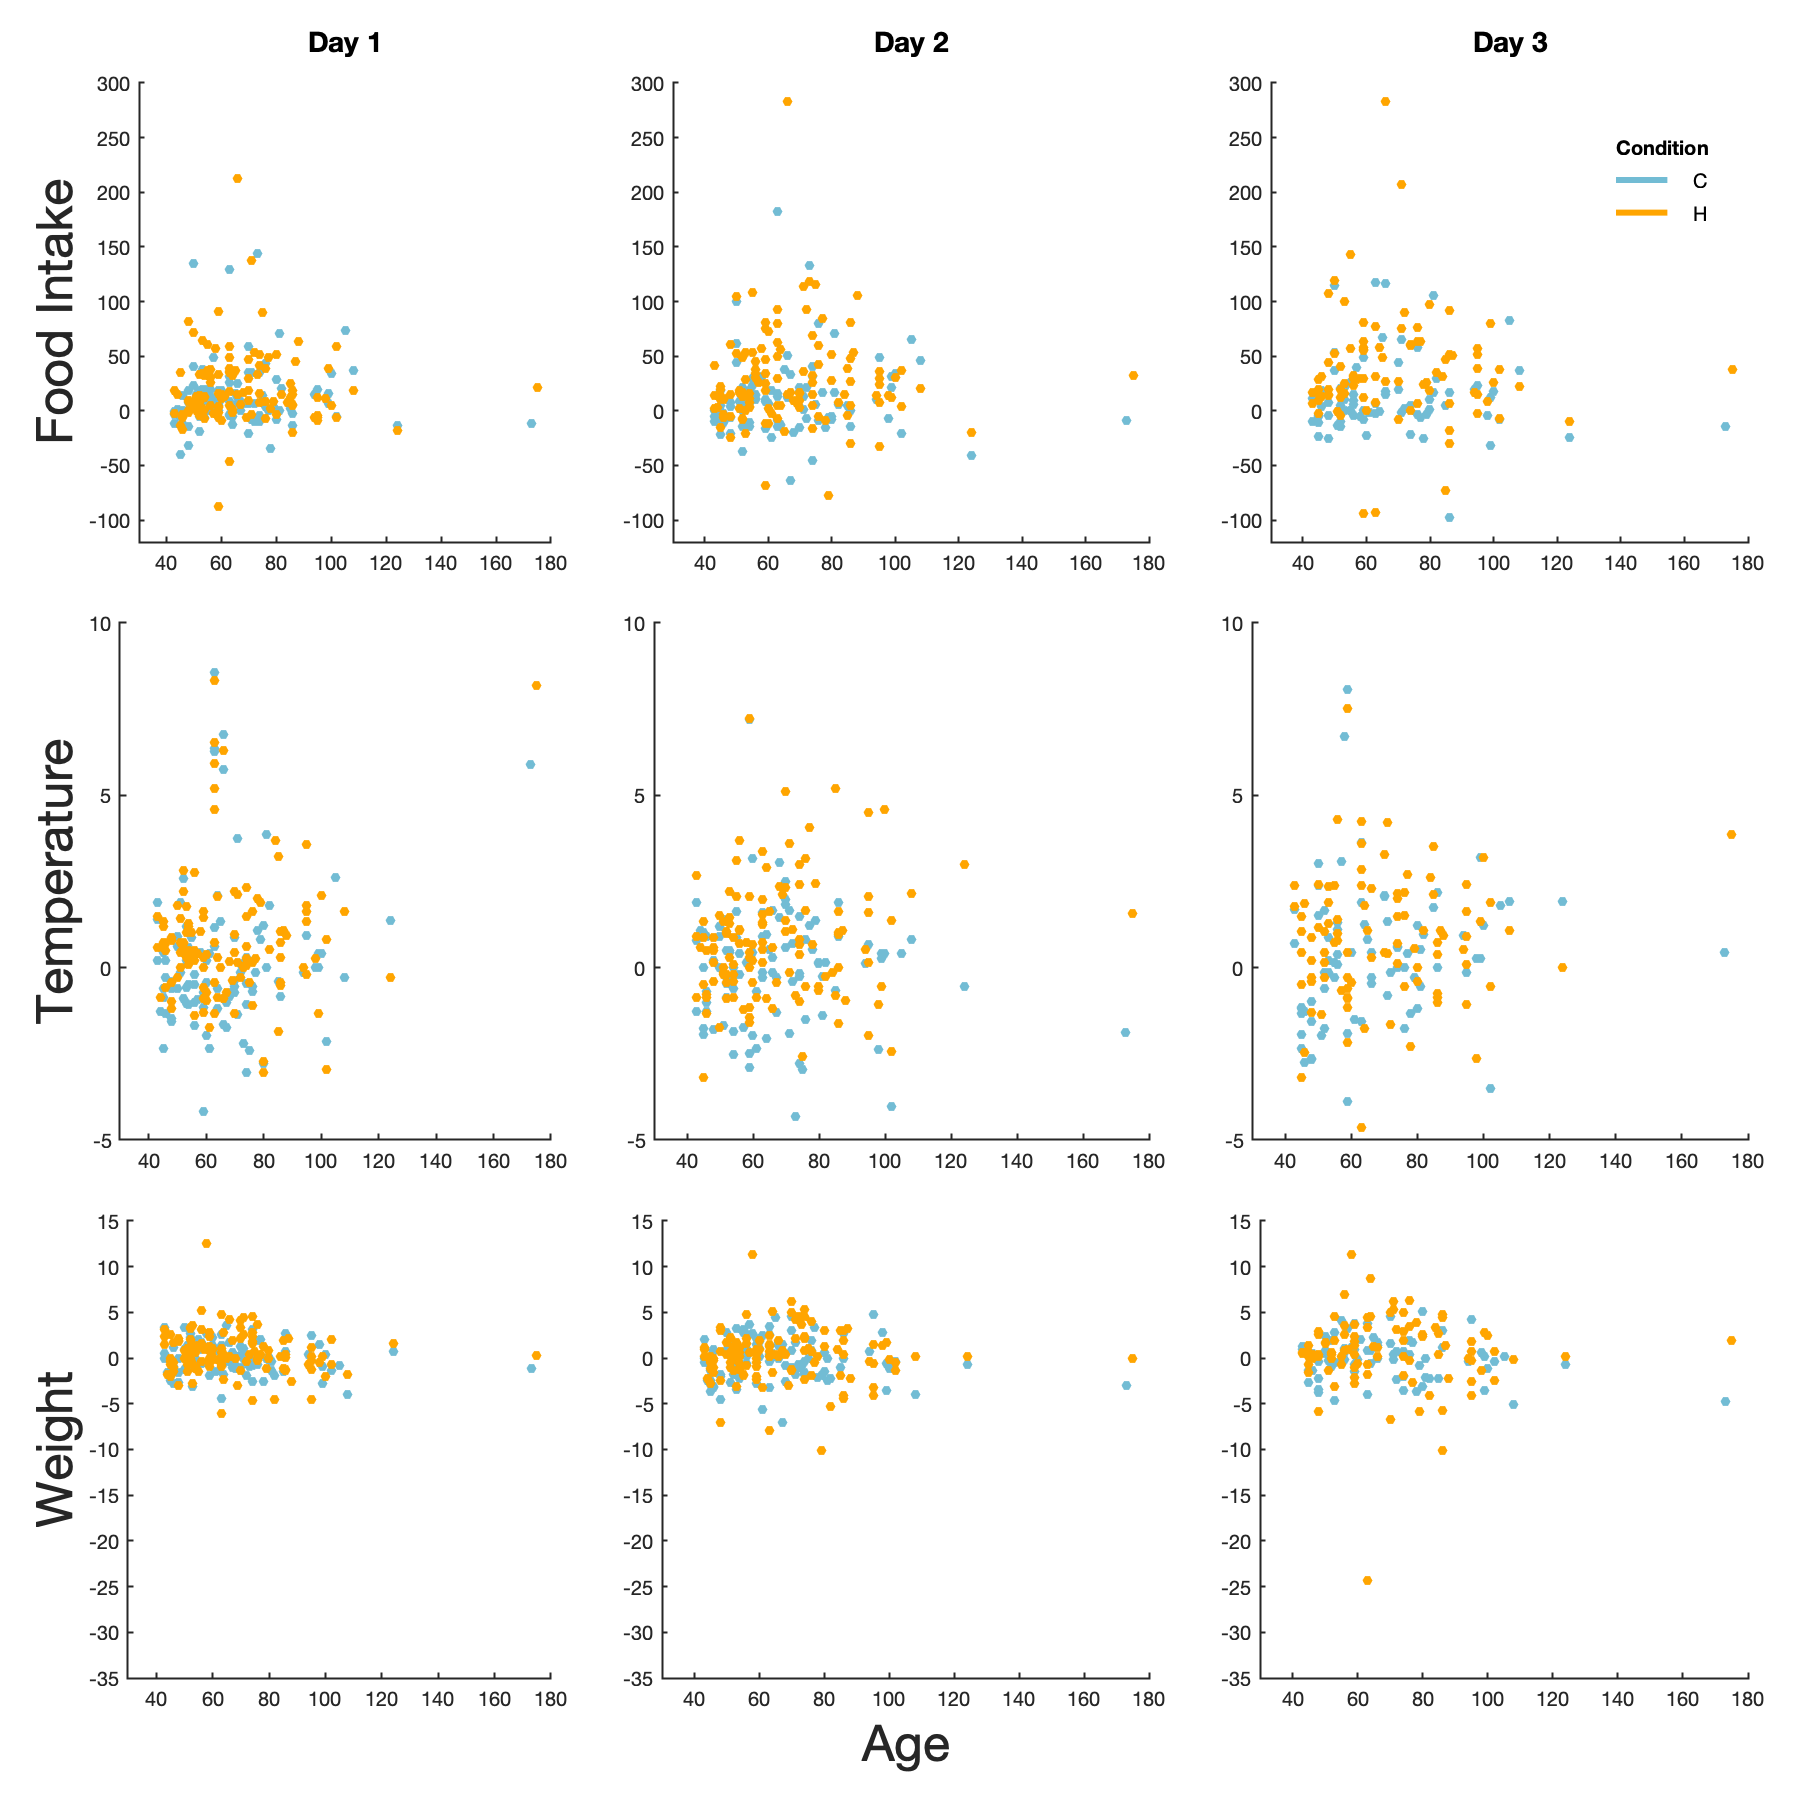


saveas(gcf,'three_by_three','epsc')
saveas(gcf,'three_by_three','jpeg')
saveas(gcf,'three_by_three','fig')

%Perc Temp and Perc Food Intake Aligned Vertically

 g(1,1)=gramm('x',alldataV.Day,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
g(1,1).stat_boxplot('width',0.5,'dodge',0.5);
g(1,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-80,140],"YTick",-80:20:140);
g(1,1).axe_property('LineWidth',1)
g(1,1).set_names('x',[],'y','Normalized Percent Change in Food Intake','color','Condition');
g(1,1).set_text_options( "base_size",14)
g(1,1).set_layout_options('Position',[0 0.55 0.9 0.38],... %Set the position in the figure (as in standard 'Position' axe property)
    'margin_height',[0.02 0.02],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.2 0.02],...
    'redraw',false); %We deactivate automatic redrawing/resizing so that the axes stay aligned according to the margin options
g(1,1).no_legend()
g(2,1)=gramm('x',alldataV.Day,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
g(2,1).stat_boxplot('width',0.5,'dodge',0.5);
g(2,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-6,6],"YTick",-6:2:6);
g(2,1).axe_property('LineWidth',1)
g(2,1).set_names('x','Days','y','Normalized Percent Change in Temperature','color','Condition');
g(2,1).set_text_options( "base_size",14)
g(2,1).set_layout_options('Position',[0 0.1 0.9 0.38],...
    'margin_height',[0.02 0.02],...
    'margin_width',[0.2 0.02],...
    'redraw',false);
g(2,1).no_legend()
g.set_color_options('map',colormap)
figure('Position',[1000 1000 367 800]);
g.draw()
set([g(1,1).results.stat_boxplot.outliers_handle],'visible','off')
set([g(2,1).results.stat_boxplot.outliers_handle],'visible','off')

saveas(gcf,'perctemp_food_vertical','epsc')
saveas(gcf,'perctemp_food_vertical','jpeg')
saveas(gcf,'perctemp_food_vertical','fig')

%Perc Temp and Perc Food Intake Aligned Horizontally

h(1,1)=gramm('x',alldataV.Day,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
h(1,1).stat_boxplot('width',0.5,'dodge',0.5);
h(1,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-80,140],"YTick",-80:20:140);
h(1,1).axe_property('LineWidth',1)
h(1,1).set_names('x','Days','y','Normalized Percent Change in Food Intake','color','Condition');
h(1,1).set_text_options( "base_size",14)
h(1,1).no_legend()

h(1,2)=gramm('x',alldataV.Day,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
h(1,2).stat_boxplot('width',0.5,'dodge',0.5);
h(1,2).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-6,6],"YTick",-6:2:6);
h(1,2).axe_property('LineWidth',1)
h(1,2).set_names('x','Days','y','Normalized Percent Change in Temperature','color','Condition');
h(1,2).set_text_options( "base_size",14)
h(1,2).no_legend()

h.set_color_options('map',colormap)
figure('Position',[100 100 667 367]);
h.draw()
set([h(1,1).results.stat_boxplot.outliers_handle],'visible','off')
set([h(1,2).results.stat_boxplot.outliers_handle],'visible','off')

saveas(gcf,'perctemp_food_horizontal','epsc')
saveas(gcf,'perctemp_food_horizontal','jpeg')
saveas(gcf,'perctemp_food_horizontal','fig')

%Figure Containing Perc Temp M/F/All Data 

i(1,2)=gramm('x',alldataV.Day,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Sex_M_F_=="F");
i(1,2).stat_boxplot('width',0.5,'dodge',0.5);
i(1,2).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-6,6],"YTick",-6:2:6,'LineWidth',1);
i(1,2).set_names('x','Days','y',[],'color','Condition');
i(1,2).set_title('Females')
i(1,2).set_text_options( "base_size",14)
i(1,2).no_legend()

i(1,3)=gramm('x',alldataV.Day,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Sex_M_F_=="M");
i(1,3).stat_boxplot('width',0.5,'dodge',0.5);
i(1,3).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-6,6],"YTick",-6:2:6,'LineWidth',1);
i(1,3).set_names('x','Days','y',[],'color','Condition');
i(1,3).set_title('Males')
i(1,3).set_text_options( "base_size",14)
i(1,3).no_legend()

i(1,1)=gramm('x',alldataV.Day,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
i(1,1).stat_boxplot('width',0.5,'dodge',0.5);
i(1,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-6,6],"YTick",-6:2:6,'LineWidth',1);
i(1,1).set_title('All Data')
i(1,1).set_names('x','Days','y','Normalized Percent Change in Temperature','color','Condition');
i(1,1).set_text_options( "base_size",14)
i(1,1).no_legend()

i.set_color_options('map',colormap)
figure('Position',[1000 1000 1000 400]);
i.draw()

set([i(1,1).results.stat_boxplot.outliers_handle],'visible','off')
set([i(1,2).results.stat_boxplot.outliers_handle],'visible','off')
set([i(1,3).results.stat_boxplot.outliers_handle],'visible','off')

saveas(gcf,'perctempsex','epsc')
saveas(gcf,'perctempsex','jpeg')
saveas(gcf,'perctempsex','fig')

%Figure Containing Perc Temp Robo3+/+, WT, All Data

x(1,1)=gramm('x',alldataV.Day,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
x(1,1).stat_boxplot('width',0.5,'dodge',0.5);
x(1,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-6,6],"YTick",-6:2:6,'LineWidth',1);
x(1,1).set_names('x','Days','y','Normalized Percent Change in Temperature','color','Condition');
x(1,1).set_title('All Data');
x(1,1).set_text_options( "base_size",14)
x(1,1).no_legend();

x(1,2)=gramm('x',alldataV.Day,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Genotype=="Robo3+/+");
x(1,2).stat_boxplot('width',0.5,'dodge',0.5);
x(1,2).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-6,6],"YTick",-6:2:6,'LineWidth',1);
x(1,2).set_names('x','Days','y',[],'color','Condition');
x(1,2).set_title('Robo3+/+');
x(1,2).set_text_options( "base_size",14)
x(1,2).no_legend()

x(1,3)=gramm('x',alldataV.Day,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Genotype=="WT");
x(1,3).stat_boxplot('width',0.5,'dodge',0.5);
x(1,3).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-6,6],"YTick",-6:2:6,'LineWidth',1);
x(1,3).set_names('x','Days','y',[],'color','Condition');
x(1,3).set_title('WT')
x(1,3).set_text_options( "base_size",14)
x(1,3).no_legend()

x.set_color_options('map',colormap)
figure('Position',[1000 1000 1000 400]);
x.draw()
set([x(1,1).results.stat_boxplot.outliers_handle],'visible','off')
set([x(1,2).results.stat_boxplot.outliers_handle],'visible','off')
set([x(1,3).results.stat_boxplot.outliers_handle],'visible','off')

saveas(gcf,'perctempgeno','epsc')
saveas(gcf,'perctempgeno','jpeg')
saveas(gcf,'perctempgeno','fig')

%Figure Containing Perc Food Intake M/F/All Data

j(1,2)=gramm('x',alldataV.Day,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Day<4 & alldataV.Sex_M_F_=="F");
j(1,2).stat_boxplot('width',0.5,'dodge',0.5);
j(1,2).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-80,140],"YTick",-80:20:140,'LineWidth',1);
j(1,2).set_names('x','Days','y',[],'color','Condition');
j(1,2).set_title('Females');
j(1,2).set_text_options( "base_size",14);
j(1,2).no_legend();

j(1,3)=gramm('x',alldataV.Day,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Day>-2 & alldataV.Sex_M_F_=="M");
j(1,3).stat_boxplot('width',0.5,'dodge',0.5);
j(1,3).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-80,140],"YTick",-80:20:140,'LineWidth',1);
j(1,3).set_names('x','Days','y',[],'color','Condition');
j(1,3).set_title('Males');
j(1,3).set_text_options( "base_size",14);
j(1,3).no_legend();

j(1,1)=gramm('x',alldataV.Day,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
j(1,1).stat_boxplot('width',0.5,'dodge',0.5);
j(1,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-80,140],"YTick",-80:20:140,'LineWidth',1);
j(1,1).set_title('All Data');
j(1,1).set_names('x','Days','y','Normalized Percent Change in Food Intake','color','Condition');
j(1,1).set_text_options( "base_size",14);
j(1,1).no_legend();

j.set_color_options('map',colormap)
figure('Position',[1000 1000 1000 400]);
j.draw()
set([j(1,1).results.stat_boxplot.outliers_handle],'visible','off')
set([j(1,2).results.stat_boxplot.outliers_handle],'visible','off')
set([j(1,3).results.stat_boxplot.outliers_handle],'visible','off')

saveas(gcf,'percfoodsex','epsc')
saveas(gcf,'percfoodsex','jpeg')
saveas(gcf,'percfoodsex','fig')

%Figure Containing Perc Food Intake Robo3+/+,WT, All Data

k(1,2)=gramm('x',alldataV.Day,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Genotype=="Robo3+/+");
k(1,2).stat_boxplot('width',0.5,'dodge',0.5);
k(1,2).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-80,140],"YTick",-80:20:140,'LineWidth',1);
k(1,2).set_names('x','Days','y',[],'color','Condition');
k(1,2).set_title('Robo3+/+');
k(1,2).set_text_options( "base_size",14);
k(1,2).no_legend();

k(1,3)=gramm('x',alldataV.Day,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Genotype=="WT");
k(1,3).stat_boxplot('width',0.5,'dodge',0.5);
k(1,3).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-80,140],"YTick",-80:20:140,'LineWidth',1);
k(1,3).set_names('x','Days','y',[],'color','Condition');
k(1,3).set_title('WT');
k(1,3).set_text_options( "base_size",14);
k(1,3).no_legend();

k(1,1)=gramm('x',alldataV.Day,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
k(1,1).stat_boxplot('width',0.5,'dodge',0.5);
k(1,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-80,140],"YTick",-80:20:140,'LineWidth',1);
k(1,1).set_title('All Data');
k(1,1).set_names('x','Days','y','Normalized Percent Change in Food Intake','color','Condition');
k(1,1).set_text_options( "base_size",14);
k(1,1).no_legend();

k.set_color_options('map',colormap)
figure('Position',[1000 1000 1000 400]);
k.draw()
set([k(1,1).results.stat_boxplot.outliers_handle],'visible','off')
set([k(1,2).results.stat_boxplot.outliers_handle],'visible','off')
set([k(1,3).results.stat_boxplot.outliers_handle],'visible','off')

saveas(gcf,'percfoodgeno','epsc')
saveas(gcf,'percfoodgeno','jpeg')
saveas(gcf,'percfoodgeno','fig')

%Figure Containing Perc Weight M/F/All Data

l(1,2)=gramm('x',alldataV.Day,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Sex_M_F_=="F");
l(1,2).stat_boxplot('width',0.5,'dodge',0.5);
l(1,2).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-8,8],"YTick",-8:2:8,'LineWidth',1);
l(1,2).set_names('x','Days','y',[],'color','Condition');
l(1,2).set_title('Females');
l(1,2).set_text_options( "base_size",14);
l(1,2).no_legend();

l(1,3)=gramm('x',alldataV.Day,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Sex_M_F_=="M");
l(1,3).stat_boxplot('width',0.5,'dodge',0.5);
l(1,3).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-8,8],"YTick",-8:2:8,'LineWidth',1);
l(1,3).set_names('x','Days','y',[],'color','Condition');
l(1,3).set_title('Males');
l(1,3).set_text_options( "base_size",14);
l(1,3).no_legend();

l(1,1)=gramm('x',alldataV.Day,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
l(1,1).stat_boxplot('width',0.5,'dodge',0.5);
l(1,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-8,8],"YTick",-8:2:8,'LineWidth',1);
l(1,1).set_title('All Data');
l(1,1).set_names('x','Days','y','Normalized Percent Change in Weight','color','Condition');
l(1,1).set_text_options( "base_size",14);
l(1,1).no_legend();

l.set_color_options('map',colormap)
figure('Position',[1000 1000 1000 400]);
l.draw()
set([l(1,1).results.stat_boxplot.outliers_handle],'visible','off')
set([l(1,2).results.stat_boxplot.outliers_handle],'visible','off')
set([l(1,3).results.stat_boxplot.outliers_handle],'visible','off')

saveas(gcf,'percweightsex','epsc')
saveas(gcf,'percweightsex','jpeg')
saveas(gcf,'percweightsex','fig')

%Figure Containing Perc Weight Robo3+/+,WT,All Data

m(1,2)=gramm('x',alldataV.Day,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Genotype=="Robo3+/+");
m(1,2).stat_boxplot('width',0.5,'dodge',0.5);
m(1,2).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-8,8],"YTick",-8:2:8,'LineWidth',1);
m(1,2).set_names('x','Days','y',[],'color','Condition');
m(1,2).set_title('Robo3+/+');
m(1,2).set_text_options( "base_size",14);
m(1,2).no_legend();

m(1,3)=gramm('x',alldataV.Day,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4 & alldataV.Genotype=="WT");
m(1,3).stat_boxplot('width',0.5,'dodge',0.5);
m(1,3).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-8,8],"YTick",-8:2:8,'LineWidth',1);
m(1,3).set_names('x','Days','y',[],'color','Condition');
m(1,3).set_title('WT');
m(1,3).set_text_options( "base_size",14);
m(1,3).no_legend();

m(1,1)=gramm('x',alldataV.Day,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day>-2 & alldataV.Day<4);
m(1,1).stat_boxplot('width',0.5,'dodge',0.5);
m(1,1).axe_property('YScale','linear',"XTick",-1:3,'YLim',[-8,8],"YTick",-8:2:8,'LineWidth',1);
m(1,1).set_title('All Data');
m(1,1).set_names('x','Days','y','Normalized Percent Change in Weight','color','Condition');
m(1,1).set_text_options( "base_size",14);
m(1,1).no_legend();

m.set_color_options('map',colormap)
figure('Position',[1000 1000 1000 400]);
m.draw()
set([m(1,1).results.stat_boxplot.outliers_handle],'visible','off')
set([m(1,2).results.stat_boxplot.outliers_handle],'visible','off')
set([m(1,3).results.stat_boxplot.outliers_handle],'visible','off')

saveas(gcf,'percweightgeno','epsc')
saveas(gcf,'percweightgeno','jpeg')
saveas(gcf,'percweightgeno','fig')